# Communication System Assignment 3 - Questions 6 to 10

clear; clc; 

% System Parameters
Ac = 2;                 
fc = 1;                 
N0 = 0.1;               
R = 1; C = 1; RC = R*C;

% Simulation Parameters
fs_sim = 1000;          
T_dur = 100;            
t = 0:1/fs_sim:T_dur-1/fs_sim;
L_sim = length(t);      


## 6: System Frequency Response Analysis

W_plot = 5; % This acts as the Ideal LPF Cutoff
f_vec = linspace(0, 10, 1000); 

% Magnitude Response (High Pass Filter Behavior based on formula)
H_RC_mag = abs( (1j*2*pi*f_vec*RC) ./ (1 + 1j*2*pi*f_vec*RC) );
V_mag = H_RC_mag;

% Apply Ideal Low Pass Filter (Windowing)
V_mag(f_vec > W_plot) = 0;

% Calculations for requested info 
f_corner_RC = 1 / (2 * pi * RC);   % 3dB frequency of the RC High-pass
f_cutoff_LPF = W_plot;             % The hard cutoff defined in W_plot
passband_min = f_corner_RC;
passband_max = f_cutoff_LPF;

fprintf('Analysis Results:\n');

Analysis Results:


fprintf('RC Corner Frequency (HPF):  %.4f Hz\n', f_corner_RC);

RC Corner Frequency (HPF):  0.1592 Hz


fprintf('LPF Cutoff Frequency:       %.4f Hz\n', f_cutoff_LPF);

LPF Cutoff Frequency:       5.0000 Hz


fprintf('Effective Passband:         %.4f Hz to %.4f Hz\n', passband_min, passband_max);

Effective Passband:         0.1592 Hz to 5.0000 Hz


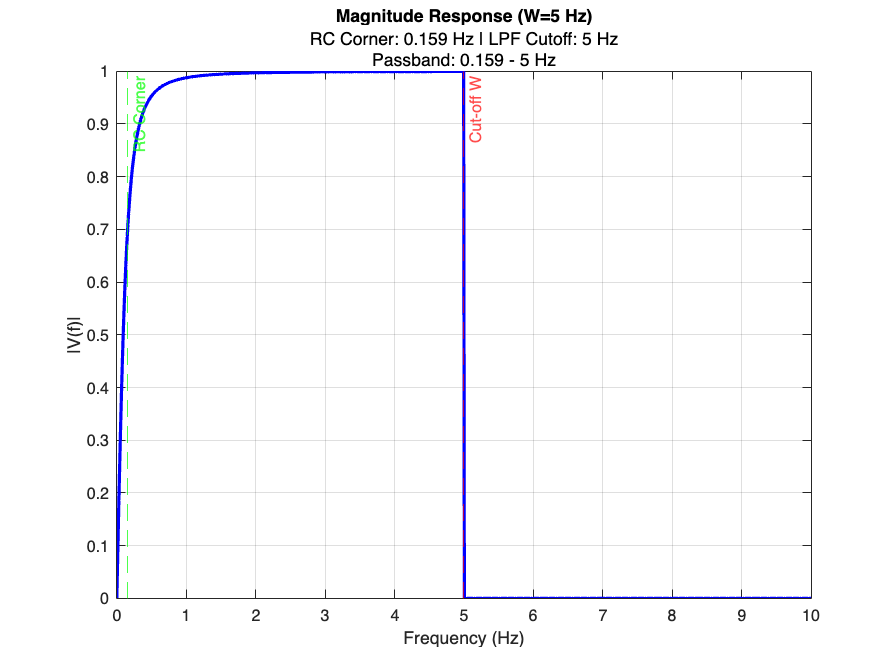

% Plotting
figure('Name', 'Sec 6: Freq Response');
plot(f_vec, V_mag, 'b', 'LineWidth', 2); grid on;
xline(W_plot, '--r', 'Cut-off W');
xline(f_corner_RC, '--g', 'RC Corner'); 

xlabel('Frequency (Hz)'); ylabel('|V(f)|');
title(['Magnitude Response (W=' num2str(W_plot) ' Hz)']);

% Add info to the plot explicitly
subtitle({['RC Corner: ' num2str(f_corner_RC, '%.3f') ' Hz | LPF Cutoff: ' num2str(f_cutoff_LPF) ' Hz'], ...
          ['Passband: ' num2str(passband_min, '%.3f') ' - ' num2str(passband_max) ' Hz']});

drawnow; 

## Section 7: SNR Theory & Plotting

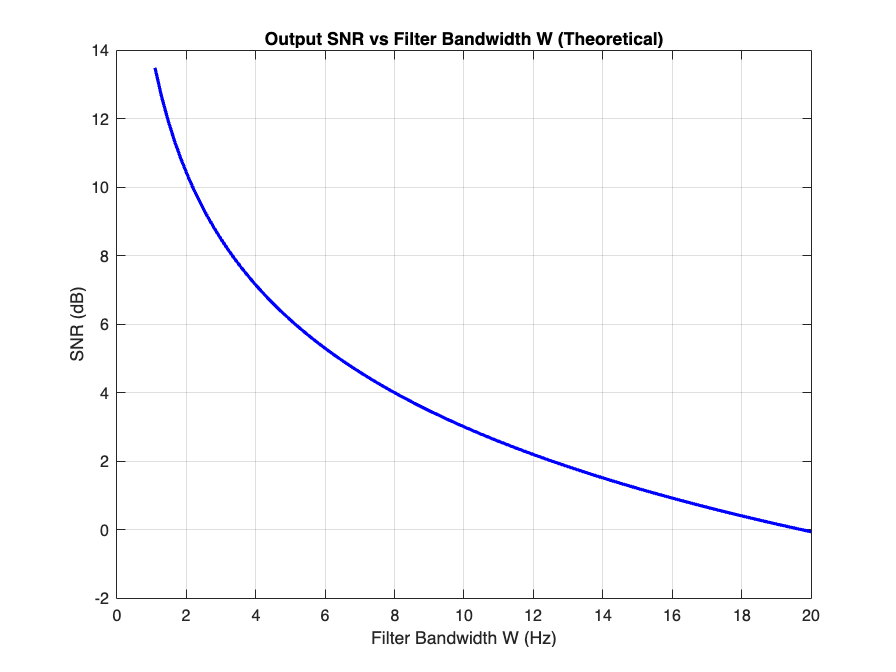

% 1. Define Functions
Ps_theory_func = @(f_c) (Ac^2/2) * ( (2*pi*f_c*RC)^2 / (1 + (2*pi*f_c*RC)^2) );
Pn_theory_func = @(W) N0 * (W - (1/(2*pi*RC)) * atan(2*pi*RC*W));

% 2. Calculate Curve Data
W_vec = linspace(fc + 0.1, 20, 100); 
SNR_theory_lin = zeros(size(W_vec));
Ps_const = Ps_theory_func(fc);

for i = 1:length(W_vec)
    SNR_theory_lin(i) = Ps_const / Pn_theory_func(W_vec(i));
end
SNR_theory_dB_Curve = 10*log10(SNR_theory_lin); 

% 3. Plot Section 7 Figure (Theoretical Only)
figure('Name', 'Sec 7: Theoretical SNR');
plot(W_vec, SNR_theory_dB_Curve, 'b-', 'LineWidth', 2); 
grid on;
xlabel('Filter Bandwidth W (Hz)'); 
ylabel('SNR (dB)');
title('Output SNR vs Filter Bandwidth W (Theoretical)');

drawnow; 

## Section 8: Cut-off Frequency Mismatch

% 8.1 W = fc
W_case = fc;
SNR_8_dB = 10*log10(Ps_const / Pn_theory_func(W_case));
fprintf('  > SNR at W = fc (%g Hz): %.2f dB\n', fc, SNR_8_dB);

  > SNR at W = fc (1 Hz): 14.01 dB


% ADDED: Signal Power Loss Calculation
% Ps_const is the signal power after RC filter.
% Since LPF is ideal and W >= fc, the signal passes completely.
Ps_W_inf = Ps_const; % Signal Power if W -> inf (only RC filter effect)
Ps_W_fc  = Ps_const; % Signal Power if W = fc (Ideal LPF passes fc)

Sig_Loss_dB = 10*log10(Ps_W_fc / Ps_W_inf);
fprintf('  > Signal Power Loss (W=fc vs W->inf): %.2f dB\n', Sig_Loss_dB);

  > Signal Power Loss (W=fc vs W->inf): 0.00 dB


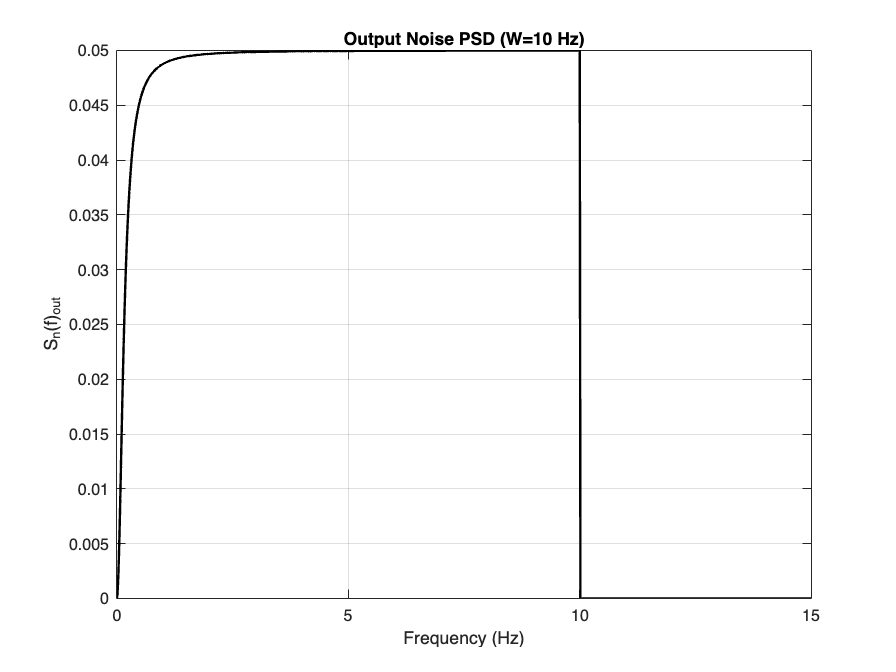

% 8.2 Noise PSD Plot
W_psd = 10;
f_psd = linspace(0, 15, 1000);
Sn_out = (N0/2) * abs((1j*2*pi*f_psd*RC)./(1 + 1j*2*pi*f_psd*RC)).^2;
Sn_out(f_psd > W_psd) = 0; 

figure('Name', 'Sec 8: Output Noise PSD');
plot(f_psd, Sn_out, 'k', 'LineWidth', 1.5); grid on;
xlabel('Frequency (Hz)'); ylabel('S_n(f)_{out}');
title(['Output Noise PSD (W=' num2str(W_psd) ' Hz)']);

drawnow;

## Section 9: Monte Carlo Simulation & Comparison

W_sim_points = [1.5, 3, 5, 10, 15]; 
SNR_sim_dB = zeros(size(W_sim_points));
num_realizations = 20; 

% Signal Setup
s_t = Ac * cos(2*pi*fc*t);
freqs = (0:L_sim-1)*(fs_sim/L_sim); 
f_idx = freqs; f_idx(f_idx > fs_sim/2) = f_idx(f_idx > fs_sim/2) - fs_sim; 
H_RC_sim = (1j*2*pi*f_idx*RC) ./ (1 + 1j*2*pi*f_idx*RC);

for k = 1:length(W_sim_points)
    Wi = W_sim_points(k);
    H_LPF_sim = double(abs(f_idx) <= Wi);
    V_sim = H_RC_sim .* H_LPF_sim;
    
    % Signal Power
    y_s = real(ifft(fft(s_t) .* V_sim));
    Ps_sim = mean(y_s.^2);
    
    % Noise Power
    Pn_accum = 0;
    sigma_noise = sqrt((N0 * fs_sim) / 2); 
    for r = 1:num_realizations
        n_t = sigma_noise * randn(1, L_sim);
        y_n = real(ifft(fft(n_t) .* V_sim));
        Pn_accum = Pn_accum + mean(y_n.^2);
    end
    SNR_sim_dB(k) = 10*log10(Ps_sim / (Pn_accum / num_realizations));
    fprintf('  > Sim W=%g Hz -> SNR=%.2f dB\n', Wi, SNR_sim_dB(k));
end

  > Sim W=1.5 Hz -> SNR=11.96 dB
  > Sim W=3 Hz -> SNR=8.48 dB
  > Sim W=5 Hz -> SNR=6.20 dB
  > Sim W=10 Hz -> SNR=2.98 dB
  > Sim W=15 Hz -> SNR=1.24 dB


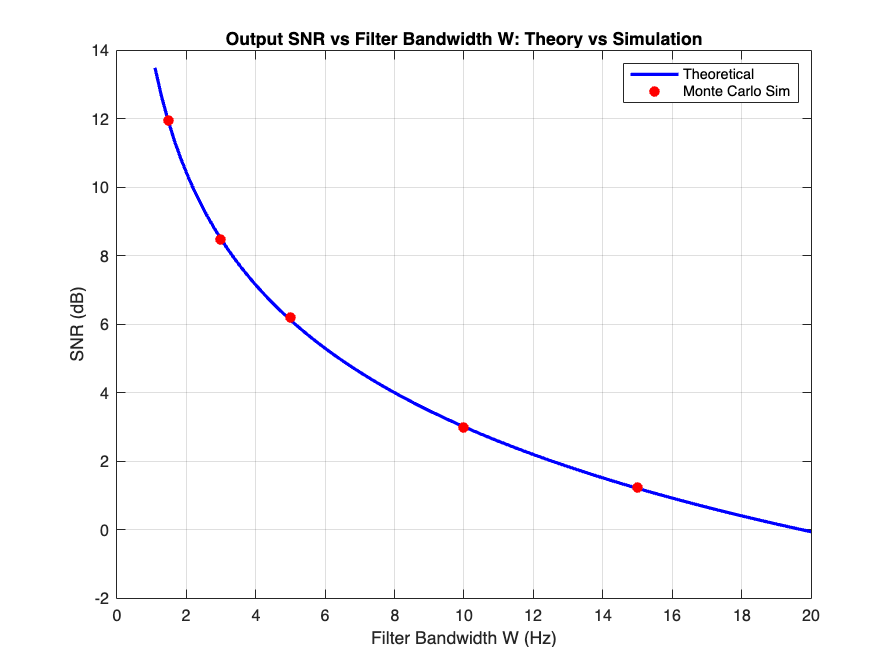


% Plot Section 9 Figure (Combined: Theory from Sec 7 + Monte Carlo)
figure('Name', 'Sec 9: Theory vs Sim');
plot(W_vec, SNR_theory_dB_Curve, 'b-', 'LineWidth', 2); % Re-plot Theory
hold on;
plot(W_sim_points, SNR_sim_dB, 'ro', 'MarkerFaceColor', 'r', 'DisplayName', 'Monte Carlo');
grid on;
legend('Theoretical', 'Monte Carlo Sim');
xlabel('Filter Bandwidth W (Hz)'); 
ylabel('SNR (dB)');
title('Output SNR vs Filter Bandwidth W: Theory vs Simulation');

drawnow;

## Section 10: Bonus

W_bonus = 5;
Beq = W_bonus - (1/(2*pi*RC))*atan(2*pi*RC*W_bonus);
fprintf('  > Equivalent Noise BW (Beq) for W=5: %.4f Hz\n', Beq);

  > Equivalent Noise BW (Beq) for W=5: 4.7551 Hz
